# **Computer Assignment 1: Spectral Analysis of EEG**

**Task 1: Calculate the power spectrum estimates of the EEG signal using the Welch's method **

Use two different sets of parameters:

1) One yielding a spectral estimate of relatively high variance, i.e. the signal looks noisy

2) One yielding a considerably more smooth spectral estimate. 

Useful commands

Welch's method:` pwelch(`[`x`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#btuf68p_sep_shared-x)`,`[`window`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#shared-window)`,`[`noverlap`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#btuf68p-noverlap)`,`[`nfft`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#btuf68p-nfft)`,fs)`

`     x = input signal; window = Hamming window length given as an integer for samples; noverlap = number of overlapping samples; nfft = number of discrete DFT points (no. of frequencies to compute DFT); fs = sampling frequency of the signal`

`    e.g. pwelch[x, 128, 64, 128, fs].`

Plotting, e.g.:` figure, plot, title, xlabel, ylabel`

**Note: **If your data is not oscillating around zero, you can shift it by substracting the mean values from the data, e.g.` EEG - mean(EEG)`

% ADD YOUR CODE HERE7
fs = 100;

[x,Fs,Start_date,Start_time,Label,Dimension,Coef,Nmb_chans,N] = readedf_EX1('sc4002e0.rec',0,0,360);

%creating a time vector
N = length(x);
tv = (0:N-1) / fs

%calculating PSD
[psd1, freq1] = pwelch(x, 500, 300, 500, fs)
[psd2, freq2] = pwelch(x, 6000, 100, 100, fs);

%plotting the input signal
figure 
plot(tv, x)
title('Original Signal in time-domain')
xlabel('Time (sec)')
xlim([0,360])
ylabel('Amplitude')
grid on

tv =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



%plotting PSD of noisy and smooth signal
figure

psd1 =   454.6775
  609.7219
  201.4284
  112.3920
   68.7908
   43.8475
   28.2650
   21.9907
   15.3025
   12.5448


subplot(1,2,1)
plot(freq2, 10*log10(psd2))
title('Welch Power Spectral Density Element (Noisy)')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')
grid on

subplot(1,2,2)
plot(freq1, 10*log10(psd1))
title('Welch Power Spectral Density Element (Smooth)')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')
grid on



**Task 2: Perform time-frequency analysis on the EEG signal**

Use again two sets of parameters, similarly to Task 1. 

Useful commands

`spectrogram(x, window, noverlap, f, fs) `

`all parameters same as Welch method`

`    e.g. spectrogram(x, 128, 64, 128, fs)`

Color scale manipulation `set(gca, 'Clim', [-100 45]);`

Plotting, e.g.:` figure, plot, title, xlabel, ylabel`

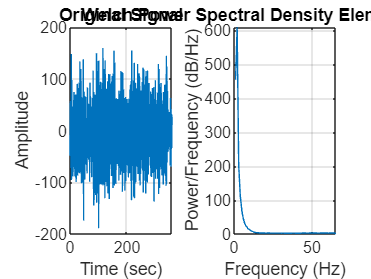

% ADD YOUR CODE HERE

[s1,f1, t1] = spectrogram(x, 128, 64, 128, fs)
[s2,f2, t2] = spectrogram(x, 6000, 100, 100, fs)


figure
subplot(1,2,1)
imagesc(f1, t1, 10*log10(abs(s1)))
title('Smooth spectrogram')
axis xy

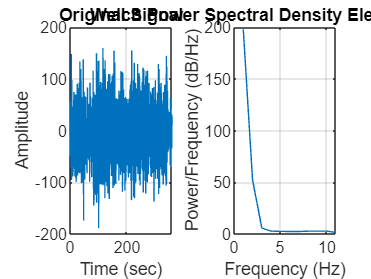

xlabel('Time (sec)')
ylabel('Frequency (Hz)')

colorbar;

subplot(1,2,2)
imagesc(f2, t2, 10*log10(abs(s2)))
title('Noisy spectrogram')
axis xy
xlabel('Time (sec)')
ylabel('Frequency (Hz)')
colorbar;